clear;clc;

R = 10; L = 1e-3; C = 100e-6; %Circuito RLC serie

G = tf(1/(L*C),[1 R/L 1/(L*C)]) %Función de transferencia 


G =
 
          1e07
  --------------------
  s^2 + 10000 s + 1e07
 
Continuous-time transfer function.



N = 10000;
frec = logspace(0,10,N); %Frecuencia en radianes (décadas)

BODE_omega_mag = []; %Magnitud/rads
BODE_hertz_mag = []; %Magnitud/hertz
BODE_omega_angle = []; %Ángulo/rads
BODE_hertz_angle = []; %Ángulo/hertz

for i = frec %Evalúa cada valor

    BODE_omega_mag(end+1) = 20*log10(abs(evalfr(G,i*j)));
    BODE_hertz_mag(end+1) = 20*log10(abs(evalfr(G,i*2*pi*j)));
    BODE_omega_angle(end+1) = 180/pi*angle(evalfr(G,i*j));
    BODE_hertz_angle(end+1) = 180/pi*angle(evalfr(G,i*2*pi*j));

end

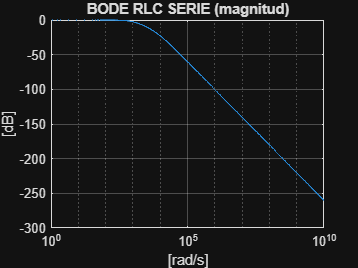

figure;
semilogx(frec,BODE_omega_mag)
title('BODE RLC SERIE (magnitud)')
ylabel('[dB]')
xlabel('[rad/s]')
grid on;

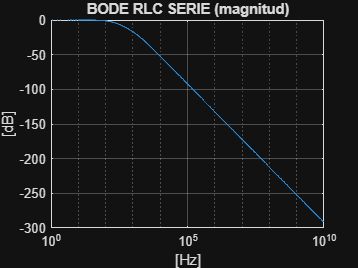

semilogx(frec,BODE_hertz_mag)
title('BODE RLC SERIE (magnitud)')
ylabel('[dB]')
xlabel('[Hz]')
grid on;

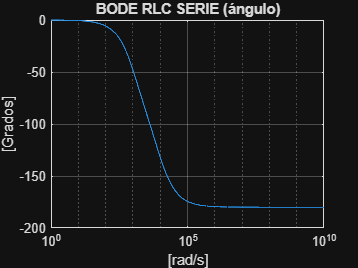

figure;
semilogx(frec,BODE_omega_angle)
title('BODE RLC SERIE (ángulo)')
ylabel('[Grados]')
xlabel('[rad/s]')
grid on;

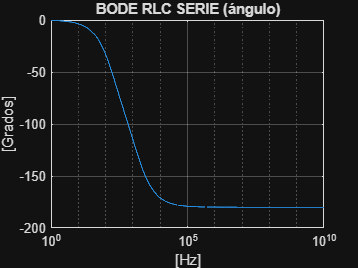

semilogx(frec,BODE_hertz_angle)
title('BODE RLC SERIE (ángulo)')
ylabel('[Grados]')
xlabel('[Hz]')
grid on;

%Actividad en clase

%Impedancias inversor final
R1 = 10e3;
R2 = 10e3;
%Impedancias comienzo
R3 = 10e3;
R4 = 10e3;
C1 = 1e-6;
C2 = 1e-12;

Gx = tf([R1*R3*R4*C2 R1*R3],[R2*R4*R3*C1 R2*R4])


Gx =
 
    s + 1e08
  -------------
  1e06 s + 1e08
 
Continuous-time transfer function.



Bx_omega_mag = []; %Magnitud/rads
Bx_hertz_mag = []; %Magnitud/hertz
Bx_omega_angle = []; %Ángulo/rads
Bx_hertz_angle = []; %Ángulo/hertz

for i = frec %Evalúa cada valor

    Bx_omega_mag(end+1) = 20*log10(abs(evalfr(Gx,i*j)));
    Bx_hertz_mag(end+1) = 20*log10(abs(evalfr(Gx,i*2*pi*j)));
    Bx_omega_angle(end+1) = 180/pi*angle(evalfr(Gx,i*j));
    Bx_hertz_angle(end+1) = 180/pi*angle(evalfr(Gx,i*2*pi*j));

end

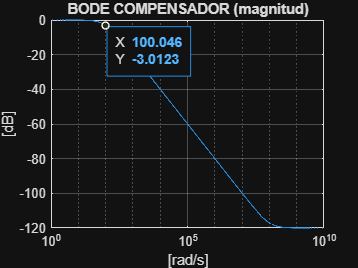

figure;
semilogx(frec,Bx_omega_mag)
title('BODE COMPENSADOR (magnitud)')
ylabel('[dB]')
xlabel('[rad/s]')
grid on;

ax = gca;
chart = ax.Children(1);
datatip(chart,100,-3.01);

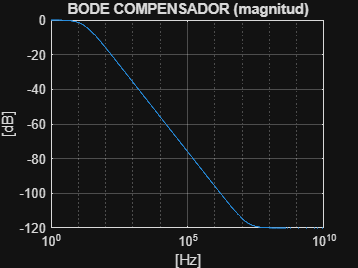

semilogx(frec,Bx_hertz_mag)
title('BODE COMPENSADOR (magnitud)')
ylabel('[dB]')
xlabel('[Hz]')
grid on;

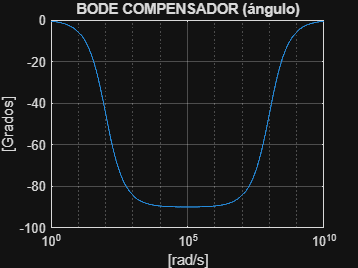

figure;
semilogx(frec,Bx_omega_angle)
title('BODE COMPENSADOR (ángulo)')
ylabel('[Grados]')
xlabel('[rad/s]')
grid on;

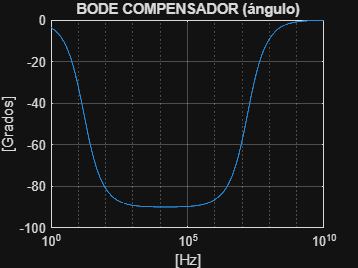

semilogx(frec,Bx_hertz_angle)
title('BODE COMPENSADOR (ángulo)')
ylabel('[Grados]')
xlabel('[Hz]')
grid on;

%Actividad reto

R1_1 = 100; C1_1 = 22.5e-6; L1_1 = 112.54e-3; %Pasa alto
R1_2 = 100; C1_2 = 15.915e-6; L1_2 = 159.15e-3; %Pasa banda

G1 = tf([1 0 0],[1 R1_1/L1_1 1/(L1_1*C1_1)])


G1 =
 
            s^2
  ------------------------
  s^2 + 888.6 s + 3.949e05
 
Continuous-time transfer function.



G2 =
 
          628.3 s
  ------------------------
  s^2 + 628.3 s + 3.948e05
 
Continuous-time transfer function.


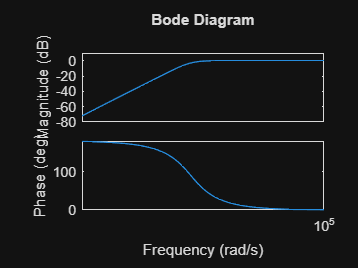

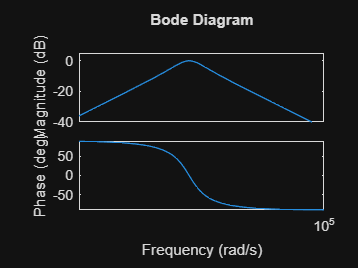

G2 = tf([R1_2/L1_2 0],[1 R1_2/L1_2 1/(L1_2*C1_2)])

bode(G1) %Pasa alto
bode(G2) %Pasa banda

B1_hertz_mag = []; %Magnitud/hertz
B2_hertz_mag = []; %Magnitud/hertz
B1_hertz_angle = []; %Ángulo/hertz
B2_hertz_angle = []; %Ángulo/hertz

for i = frec %Evalúa cada valor

    B1_hertz_mag(end+1) = 20*log10(abs(evalfr(G1,i*2*pi*j)));
    B2_hertz_mag(end+1) = 20*log10(abs(evalfr(G2,i*2*pi*j)));
    B1_hertz_angle(end+1) = 180/pi*angle(evalfr(G1,i*2*pi*j));
    B2_hertz_angle(end+1) = 180/pi*angle(evalfr(G2,i*2*pi*j));

end

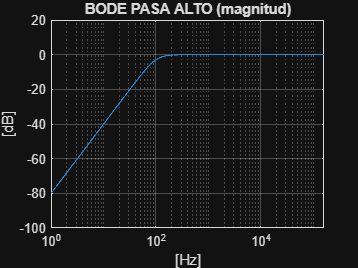

figure;
semilogx(frec,B1_hertz_mag)
title('BODE PASA ALTO (magnitud)')
ylabel('[dB]')
xlabel('[Hz]')
grid on;

xlim([0 159000])

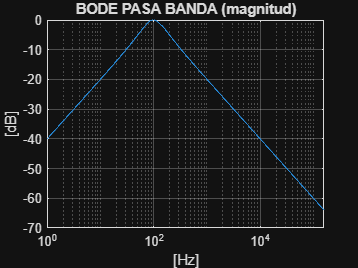


semilogx(frec,B2_hertz_mag)
title('BODE PASA BANDA (magnitud)')
ylabel('[dB]')
xlabel('[Hz]')
grid on;

xlim([0 159000])

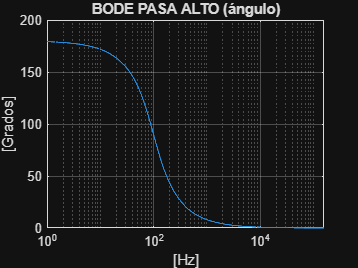

figure;
semilogx(frec,B1_hertz_angle)
title('BODE PASA ALTO (ángulo)')
ylabel('[Grados]')
xlabel('[Hz]')
grid on;

xlim([0 159000])

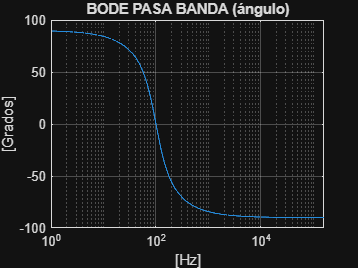


semilogx(frec,B2_hertz_angle)
title('BODE PASA BANDA (ángulo)')
ylabel('[Grados]')
xlabel('[Hz]')
grid on;

xlim([0 159000])